# Transformada de Fourier

[⇦ Información general del análisis de Fourier](matlab:open('../MainMenu.mlx'))

**Objetivos de aprendizaje**

- Comparar la serie de Fourier con la transformada de Fourier.

- Evaluar la transformada de Fourier de una función.

- Representar señales utilizando funciones continuas.

- Discutir las ondas portadoras y la modulación.

- Comparar funciones en los dominios del tiempo y de la frecuencia utilizando la transformada de Fourier.

## Introducción

Se puede utilizar una serie de Fourier compleja para analizar funciones periódicas. Recordemos la serie de Fourier compleja:


$$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$$


Graficando la magnitud de los coeficientes de Fourier, $c_n$, se pueden identificar cuáles frecuencias son dominantes.

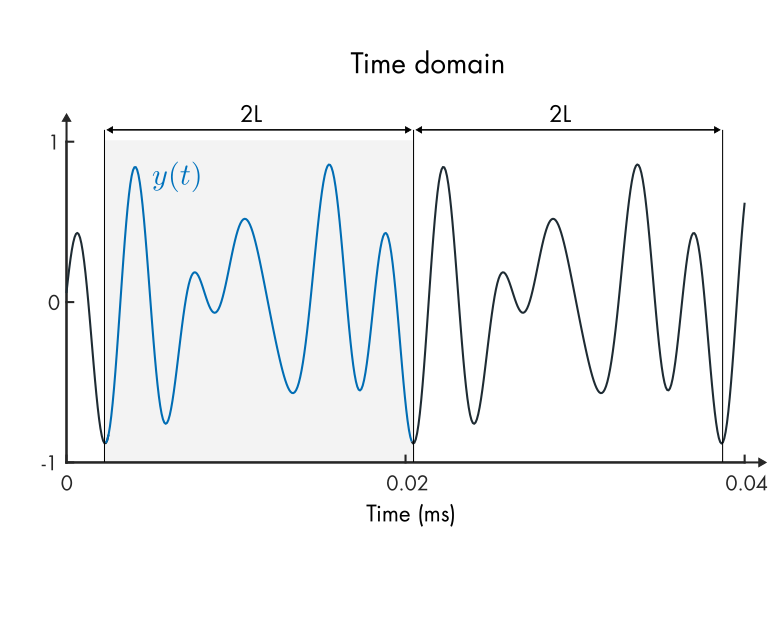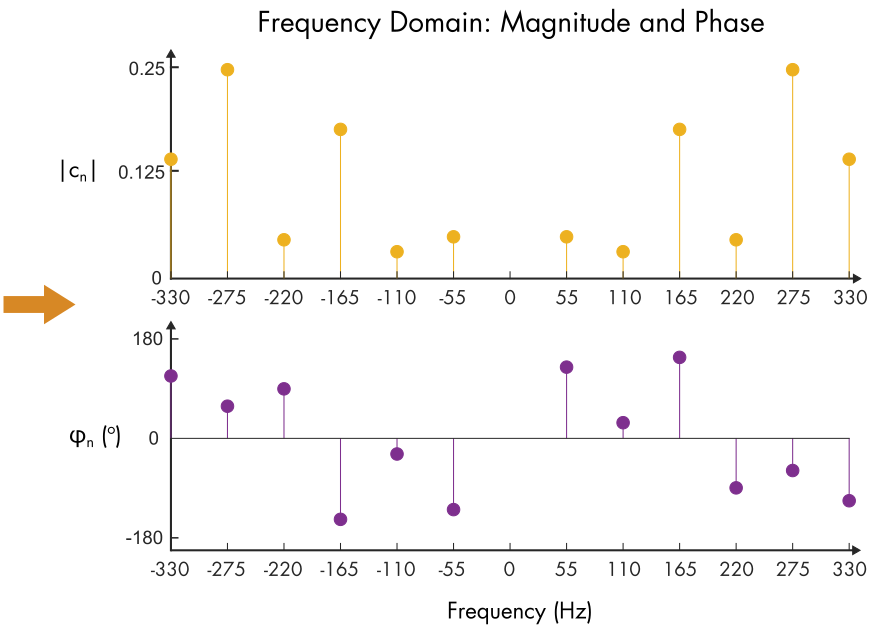

*Un acorde de guitarra simplificado en los dominios del tiempo y de la frecuencia. Primera gráfica: la función periódica *$2L$* en el dominio del tiempo. Segunda gráfica: la magnitud y fase de los coeficientes complejos *$c_n$*. Debido a que *$y(t)$* es real, los coeficientes se reflejan a frecuencias negativas.*

En este acorde, se puede ver que el C# (275 Hz) es dominante.

Debido a que la señal de audio producida por una guitarra es en gran parte periódica, una serie de Fourier compleja proporciona buenas estimaciones para el dominio de la frecuencia. Pero ¿cómo se puede calcular el dominio de la frecuencia para una función que no es periódica?

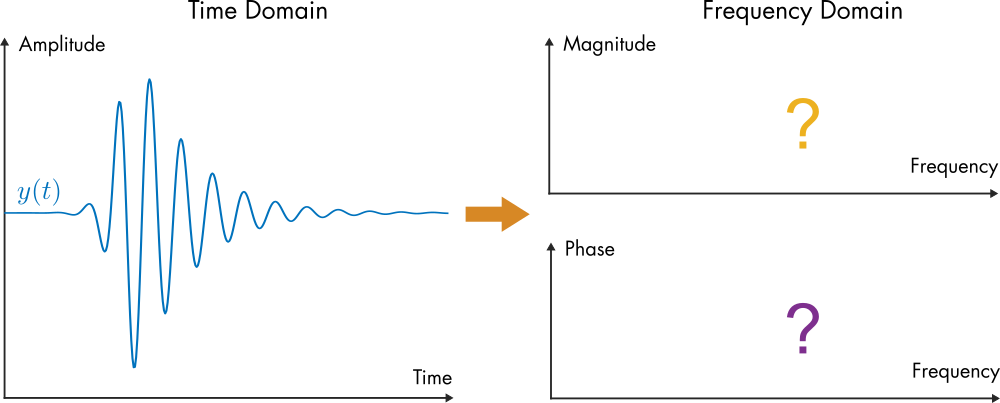

¿Cómo serán las gráficas de los dominios de la frecuencia de $y(t)$?

### Estimando una función no periódica con una serie de Fourier

Se puede asumir un dominio finito (de longitud $2L$) que abarque la mayor parte de una función no periódica y calcular los coeficientes de la serie de Fourier. Esto proporcionará información sobre el contenido de frecuencia de la función. Sin embargo, nunca ofrecerá una verdadera representación de la función original, ya que, por definición, la serie de Fourier es periódica (con período $2L$).

   **Actividad.** Las gráficas a continuación ilustran las estimaciones de series de Fourier complejas de una función no periódica.

- Ajusta `L` para cambiar el tamaño del dominio en el que se calcula la serie de Fourier.

- Ajusta `N` para cambiar el número de frecuencias utilizadas en la serie de Fourier compleja.

**Tarea 1.** Presiona **Mostrar gráfica**. Observa las cuatro gráficas.

- La gráfica etiquetada como **Reconstrucción de la serie de Fourier** muestra la función modelada por la serie de Fourier (en contraposición a la función original, $y(t)$, graficada en la primera gráfica).

- La primera gráfica del dominio de la frecuencia muestra la magnitud de los coeficientes complejos de la serie, $|c_n|$.

- La segunda gráfica del dominio de la frecuencia con la etiqueta del eje y $\angle c_n$muestra el ángulo de fase en radianes.

**Tarea 2**. Establece `L = 1` y `N = 10`. ¿Se captura precisamente ?

**Tarea 3.** Establece `L = 2` y luego `L = 3`. ¿Esto mejora la estimación?

**Tarea 4.** Con `L = 3` y `N = 10`, ¿hay suficientes modos para capturar la mayoría del contenido de frecuencia? Si no es así, aumenta el número de modos `N` hasta que se capture la mayoría del contenido de frecuencia.

**Tarea 5.** Amplía el dominio a `L = 5`. Aumenta el número de modos` N` hasta que se capture la mayoría del contenido de frecuencia.

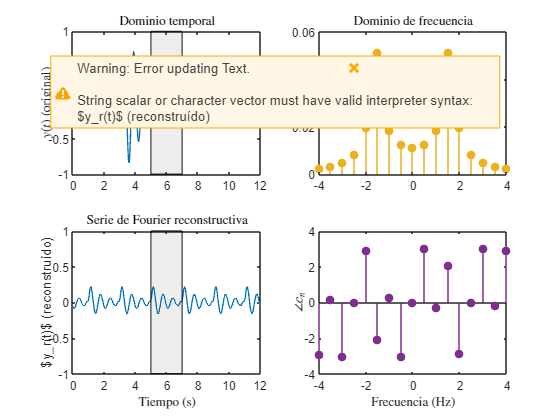

L = 1; % La mitad del ancho del dominio
N = 10; % El número de modos de Fourier para usar en la serie

fourierEstimateSech(L,N) %Función auxiliar que crea las gráficas

** Reflexiona.**

- Si se desea aumentar la resolución del dominio de la frecuencia (es decir, hacer que las ramas estén más cerca una de la otra), ¿debe aumentar el ancho del dominio `L` o el número de frecuencias `N`?

- En el caso en que` L = 5`, no se ven copias periódicas de la función en la gráfica de la reconstrucción, $y_r$. En este caso, ¿existen copias periódicas en $y_r$?

- ¿Cuán grande debe ser el dominio para que no existan copias periódicas?

- En el caso en que no existan más copias periódicas, ¿cuál será la resolución del dominio de la frecuencia (es decir, qué tan cercanas estarán las ramas entre sí)?

Aunque la serie de Fourier compleja puede proporcionar una buena estimación, nunca capturará perfectamente una función no periódica. Para que esto sea posible, el dominio en el que se calcula la serie de Fourier debe ser infinitamente grande (es decir, $L \to \infty$), lo cual no es compatible con la definición de la serie de Fourier.

La transformada de Fourier, por otro lado, tiene la capacidad de representar toda la función analíticamente en el dominio de la frecuencia. 

## Definición

La transformada de Fourier de una función $f(t)$ es


$$\hat{f}(\omega) = \int_{-\infty}^\infty f(t) e^{-i\omega t} \ dt$$


En esta definición, $\omega$ es la frecuencia angular. Para obtener la señal original $f$ desde $\hat{f}$, se puede utilizar la transformada de Fourier inversa. La transformada inversa tiene la definición complementaria


$$f(t) = \frac{1}{2 \pi} \int_{-\infty}^\infty \hat{f}(\omega) e^{i\omega t} \ dt$$


Existen varias definiciones alternativas para la transformada de Fourier. Se ha seleccionado esta definición porque coincide con las definiciones utilizadas por las funciones Symbolic Math Toolbox para la transformada de Fourier: [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) y [`ifourier`](https://www.mathworks.com/help/symbolic/sym.ifourier.html).

## Evaluación analítica de la transformada de Fourier

La transformada de Fourier se puede calcular a mano utilizando su definición o buscando en una tabla. Otra alternativa es utilizar la función [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) del Symbolic Math Toolbox. El siguiente ejemplo muestra dos de estos métodos para una distribución gaussiana. La distribución gaussiana es única porque su transformada de Fourier es otra distribución gaussiana.

 **Ejemplo.** Una función gaussiana simple con un parámetro único $a$ es


$$y(t) = e^{- a t^2}$$


Las curvas gaussianas tienen una transformada de Fourier bien definida y (relativamente) fácil de calcular.


$$\begin{array}{rl}
\hat{y}(\omega) &= \int_{-\infty}^\infty e^{-a t^2} e^{-i\omega t} \ dt
\\
&= \int_{-\infty}^\infty e^{- a( t^2 + i\omega t/a - \omega^2/(4a^2)) - \omega^2/(4a)} \ dt
\\
&= e^{ - \frac{\omega^2}{4 a}} \int_{-\infty}^\infty e^{- a (t+i\omega/(2a))^2} \ dt
\\
&= \sqrt{\frac{\pi}{a}} e^{ - \frac{ \omega^2}{4a}} 
\end{array}$$


Se puede validar el resultado calculando la serie de Fourier utilizando la función [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) del Symbolic Toolbox. 

**Tarea.** Ejecuta esta sección para calcular la transformada de Fourier.

 ** Consejo profesional.** Para ejecutar una sección rápidamente, utiliza el atajo de teclado **Ctrl+Enter**.

syms t omega % Define las variables simbólicas
syms a positive % a es una constante positiva
y = exp(-a*t^2) % Define la función
yhat = fourier(y,t,omega) % Calcula la transformada de Fourier

**Tarea. **La función $y$ y su transformada de Fourier $\hat{y}$ se grafican a continuación. Ejecuta esta sección para mostrar el gráfico. Luego utiliza el control deslizante para ajustar el valor del parámetro  y regenerar el gráfico.

% Sustituye un valor para a
aValue = 2;
transformPlot(aValue) % Función auxiliar que genera el gráfico

**  Reflexiona.**

- ¿Cómo cambia $y(t)$ a medida que se aumenta $a$?

- ¿Cómo cambia $\hat{y}$ a medida que se aumenta $a$?

- ¿Basándote en este gráfico, qué relación general parece haber entre una función en el dominio del tiempo y su contenido de frecuencia?

## Aproximación analítica de una señal real

La señal de audio de una guitarra no es realmente periódica. De hecho, se amplifica rápidamente y luego decae exponencialmente.

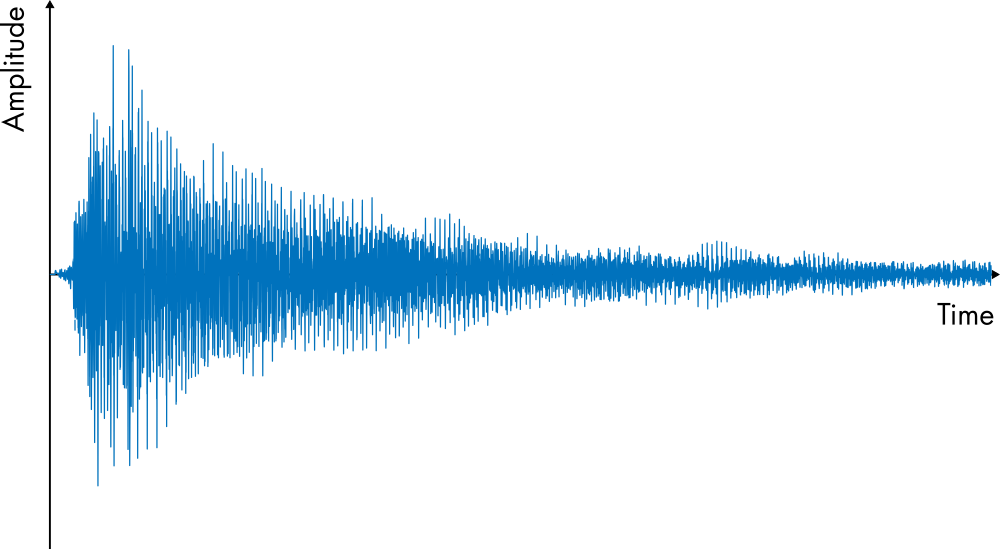

*Señal de nota "A" de guitarra en el dominio del tiempo*

En los guiones anteriores, se analizó una pequeña ventana de la señal con la serie de Fourier. Para analizar la señal no periódica completa, es útil aplicar la transformada de Fourier. Aunque la señal de audio de la guitarra contiene muchos armónicos y tiene cierto tiempo de rampa, se puede estimar razonablemente bien por el producto de una sola frecuencia y una exponencial de decaimiento:


$$y(t) = e^{-at} \sin ( 2 \pi \omega_0 t )$$


donde $a$ es la tasa de decaimiento y $\omega_0$ es la frecuencia fundamental. Para la nota A de la guitarra, una elección razonable para $\omega_0$ es $2\pi\cdot 110$, que corresponde a 110 Hz. Esta función se podría modificar fácilmente para representar mejor la señal de audio real agregando términos seno adicionales para los armónicos.

  **Actividad.** En esta actividad, construirás, graficarás y analizarás el contenido de frecuencia de la señal $y(t)$.

**Tarea 1.** Utilizando los valores predefinidos de `a`, `omega0` y `t`, calcula $y(t)$ como un vector `y` para que se pueda graficar.

**Pista**. Dado que `t` es un vector, debes usar multiplicación de elementos: .*

omega0 = 2*pi*110; % frecuencia angular correspondiente a 110 Hz
a = 1.5; % Tasa de decaimiento (por segundo)
t = 0:1/44.1e3:3; % Variable de tiempo
% Calcula y aquí



Si es correcto, y debería contener un vector de valores:

**Tarea 2.** Grafica la señal `y` en función de `t` utilizando [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html). Etiqueta los ejes utilizando [`xlabel`](https://www.mathworks.com/help/matlab/ref/xlabel.html) y [`ylabel`](https://www.mathworks.com/help/matlab/ref/ylabel.html).

figure % Crea una nueva figura
% Grafica y en función de t aquí



La función $y(t)$ no se encuentra en una forma aceptable para el análisis con la transformada de Fourier. El factor exponencial $e^{-t}$ crecerá exponencialmente para tiempos negativos, lo que impide que la integral converja. Esto tampoco es muy realista, ya que las señales de audio reales no crecen en "tiempo negativo". Para cortar la función en un tiempo especificado $t_e$ se puede usar la función escalón de Heaviside, $H(t)$ :


$$y_c(t) =  H(t-t_c) e^{-a(t-t_c)} \sin ( 2 \pi \omega_0 t )$$


Recuerda que 


$$H(t) = \left\{ \begin{array}{rl} 0 \ \ & t < 0 \\ 1 \ \ & t \geq 0 \end{array} \right.$$


**Tarea 3.** Utilizando los valores predefinidos `a`, `omega0`, `tc` y t, calcula `yc` como un vector para que pueda graficarse. Para la función escalón de Heaviside se puede utilizar la función [`heaviside`](https://www.mathworks.com/help/symbolic/heaviside.html).

tc = 0.5; % Tiempo de corte
% Calcula yc aquí
yc = NaN


**Tarea 4.** Grafica yc en función de t para ver la señal en el dominio del tiempo. ¿Cómo esperas que sea esta señal en el dominio de la frecuencia?

% Crea tu gráfica aquí



Si es correcto, tu gráfico debería aparecer así:

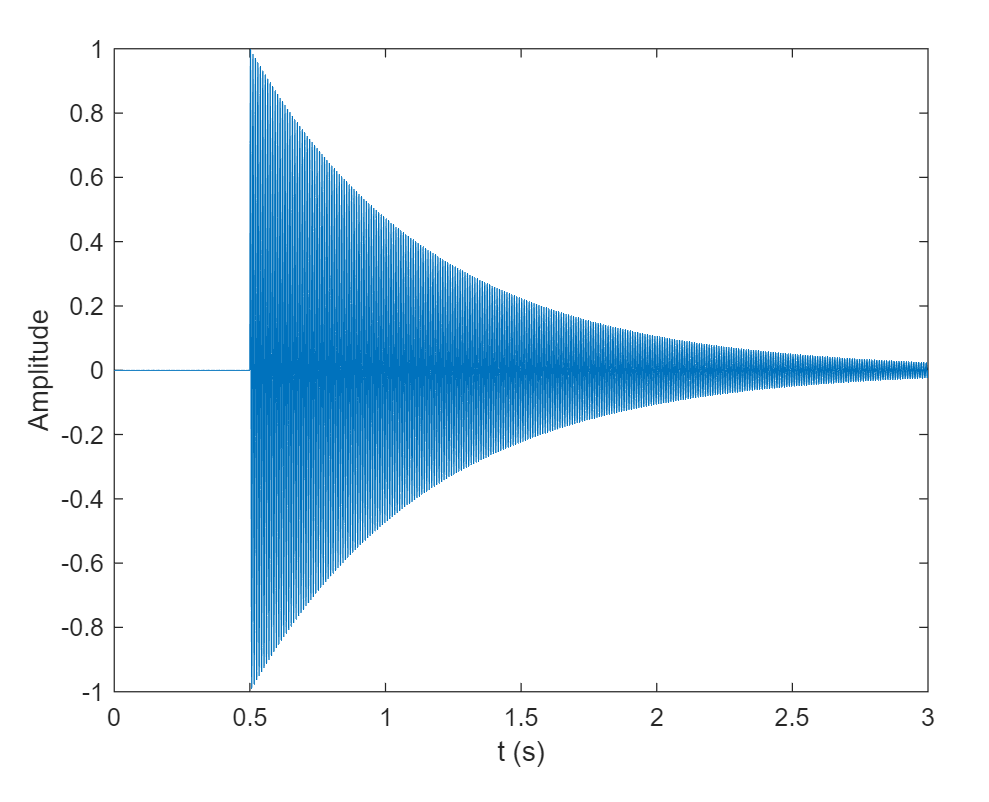

**Tarea 5**. Ejecuta esta sección para reproducir yc como sonido.

Fs = 1/(t(2)-t(1)); % La tasa de muestreo
soundsc(yc,Fs) % Reproduce el sonido

**Tarea 6.** La transformada de Fourier de $y_c$ tiene una expresión analítica. Pon a prueba tus habilidades de integración: calcula la transformada de Fourier de  a mano utilizando la definición 


$$\hat{y_c}(\omega) = \int_{-\infty}^\infty y_c(t) e^{-i\omega t} \ dt$$


**Pista:** Reescribe la función seno en términos de exponenciales complejas y divide el dominio en función de la función escalón de Heaviside.

Alternativamente, se puede calcular la transformada de Fourier utilizando el Symbolic Math Toolbox. 

**Tarea 7.** Define `yc` como una expresión simbólica. Comienza [definiendo una variable simbólica](https://www.mathworks.com/help/symbolic/create-symbolic-numbers-variables-and-expressions.html) para `t` utilizando:

Luego, expresa $y_c$ en términos de `t`. Como parte de la expresión, se pueden utilizar los valores constantes predefinidos `a`, `omega0` y `tc`. Esta expresión debe ser idéntica a la que se utilizó en la **Tarea 3**. La diferencia es que la entrada, `t`, ahora es una variable simbólica en lugar de un vector.

% Escribe tu código aquí



**Tarea 8**. Para calcular la transformada de Fourier de `yc`, utiliza la función [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) del Symbolic Math Toolbox. Define el resultado como `yhat`.

% Calcula la transformada de Fourier aquí



**Tarea 9**. Generar un gráfico de la magnitud de `yhat` $|\hat{y}|$ en el intervalo $\omega$ en `[0,1250]`. Para generar un gráfico de una expresión simbólica, utiliza [`fplot`](https://www.mathworks.com/help/matlab/ref/fplot.html) con la sintaxis

donde `f` contiene la expresión simbólica que se va a graficar y `xinterval` contiene los límites de dominio. Después de crear el gráfico, establece los límites del eje vertical en `[0,0.25]` utilizando [`ylim`](https://www.mathworks.com/help/matlab/ref/ylim.html). También etiqueta los ejes.

% Crea tu gráfico de yhat aquí



**Reflexiona.**

- Después de graficar la magnitud $|\hat{y}|$, se puede ver un pico en 110 Hz ($\approx$691 rad/s). ¿Qué factor en la función genera este pico?

- ¿Cómo sería el gráfico de la magnitud de los coeficientes de Fourier de una onda senoidal pura de 110 Hz?

- ¿Cómo es similar y diferente el gráfico de la función a la de la onda senoidal pura de los coeficientes de Fourier?

- ¿Qué efectos tienen las funciones escalón de Heaviside y decaimiento exponencial en el dominio de la frecuencia?

## Modulación de la onda portadora

Se puede considerar que la señal analizada en la actividad anterior tiene dos componentes distintas: una envolvente que cambia lentamente con el tiempo y una onda "alta" frecuencia (110 Hz) subyacente.

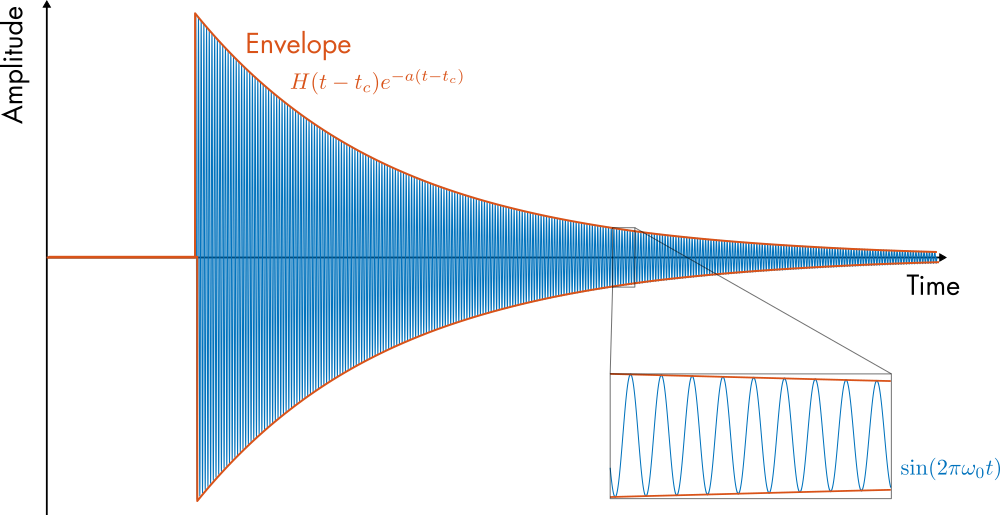

*Ilustración de los dos componentes fundamentales de la señal de audio generada en el dominio del tiempo.*

Este tipo de señal mixta es común en aplicaciones de transmisión de señales. Una onda portadora de alta frecuencia le da a una señal su frecuencia fundamental. La portadora se modula a una frecuencia más baja para codificar la información. Por ejemplo, la modulación de amplitud se utiliza en la radio AM. La frecuencia fundamental de la señal de radio se modula (en amplitud) para que coincida con la señal de audio transmitida. Para la radio AM, la frecuencia de la portadora se encuentra entre 540 y 1600 kHz. Cuando se sintoniza la radio a una estación, se sintoniza a la frecuencia de la portadora. Luego, el receptor recoge la información de audio de la modulación más lenta. 

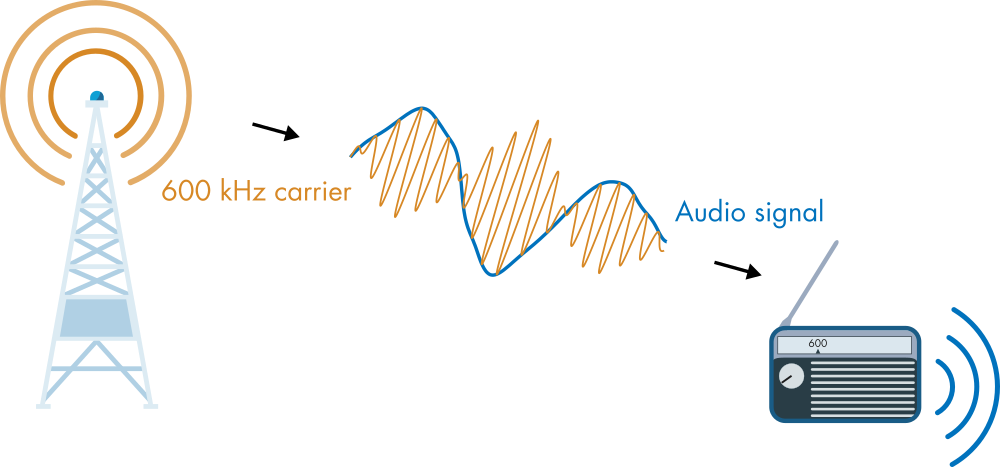

*Una radio AM sintonizada a 600 kHz recogerá la modulación de amplitud de la portadora de 600 kHz y la utilizará para alimentar el altavoz.*

Para evitar interferencias, la modulación se limita a una frecuencia máxima de 5 kHz. Esta frecuencia no es suficiente para reproducir completamente las señales de audio. Esta es una de las razones por las que la calidad de audio de la radio AM es menor que la de la radio FM.

### El Dominio de la Frecuencia

Considera las características de la señal AM modulada que se muestra en la figura de arriba. ¿Cómo esperas que sea la señal en el dominio de la frecuencia? ¿Cómo cambiará el contenido de frecuencia si se cambia la frecuencia de la portadora? En esta sección, analizarás señales moduladas utilizando la transformada de Fourier.

Al aplicar la transformada de Fourier continua, debes trabajar con funciones que tengan una transformada de Fourier bien definida (analítica). Existen varias funciones de este tipo, pero una de las más fáciles de trabajar es la función sinusoidal modulada por una gaussiana:


$$g(t) = A \sin( \omega_0 t ) e^{- \frac{(t-t_0)^2}{2 c^2 } }$$


Esta función no representa ninguna señal real en particular, pero es simple y puede ayudarte a desarrollar rápidamente la intuición sobre cómo los cambios en la portadora y la modulación afectan el contenido de frecuencia de la señal.

   **Actividad. **La gráfica de abajo muestra la función sinusoidal modulada por una gaussiana en el dominio del tiempo. Ejecuta la sección para mostrar la gráfica. Luego, ajusta cada parámetro y observa los cambios en la forma de onda.

A = 1.5; % Amplitud
f0 = 15; % Frecuencia de la portadora (Hz)
c = 0.1; % "Ancho" gaussiano
t0 = 0.5; % Posición central (s)
omega0 = f0*2*pi; % Frecuencia angular (rad/s)
sineGaussPlot(A,omega0,t0,c)

** Reflexiona. **

- ¿Cómo esperas que sea la función en el dominio de la frecuencia? (es decir, ¿cómo será la gráfica de $\hat{f}$?)

- A medida que se aumenta cada uno de los parámetros ($A$, $\omega_0$, $c$, $t_0$), ¿cómo esperas que cambie la gráfica del dominio de la frecuencia?

 **Ejercicio.** En este ejercicio, calcularás la transformada de Fourier de .

**Tarea 1.** (Opcional) Calcula la transformada de Fourier de una versión simplificada de $g(t)$ a mano:


$$g(t) = \sin(  t ) e^{- \frac{t^2}{2  } }$$


**Pista:** Reescribe la función seno en términos de exponenciales complejas. Luego, expande los términos y completa el cuadrado.

**Tarea 2.** Usa Symbolic Math Toolbox para definir la función original:


$$g(t) = A \sin( \omega_0 t ) e^{- \frac{(t-t_0)^2}{2 c^2 } }$$


Usa las variables simbólicas predefinidas en tu expresión para `g`.

% Variables simbólicas predefinidas
syms t omega real
syms omega_0 t_0 c A positive
% Escribe una expresión para g aquí



**Tarea 3.** Usa [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) para calcular la transformada de Fourier de `g` y almacena el resultado en `ghat`.

% Calcula la transformada de Fourier aquí



**Tarea 4.** Usa la función [`simplify`](https://www.mathworks.com/help/symbolic/simplify.html)  para simplificar `ghat`.

% Simplifica ghat aquí



### Componentes Real e Imaginaria

La forma funcional de $\hat{g}$ es un poco complicada. Es útil trazar el resultado para desarrollar cierta intuición sobre cómo los cambios en los parámetros afectan el contenido de frecuencia.

  ** Actividad. **En esta actividad, revisarás cómo los cambios en la función $g$ afectan el dominio de frecuencia trazando las componentes real e imaginaria de $\hat{g}$.

**Tarea 1.** Haz clic en **Mostrar gráficos**.

% Esto traza el sinusoides modulado por una gaussiana y su transformada de Fourier
A = 1.5; % Amplitud
f0 = 15; % Frecuencia de la portadora (Hz)
c = 0.1; % "Ancho" gaussiano
t0 = 0.5; % Posición central (s)
omega0 = f0*2*pi; % Frecuencia angular (rad/s)
 

% Calcula ghat 
omega = linspace(-250,250,5e3);
ghat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
    exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));
sineGaussComplexPlot(omega,ghat,A,omega0,t0,c) % Función auxiliar que genera el gráfico

**Tarea 2.** Aumenta cada parámetro de forma independiente. ¿Cómo cambia el gráfico del dominio de frecuencia al aumentar cada uno?

**Tarea 3.** Deberías notar dos copias muy similares en el dominio de frecuencia en frecuencias negativas y positivas. Establece $t_0$ en un valor relativamente pequeño para hacer que las diferencias sean más obvias. ¿Cómo parecen estar relacionadas estas copias?

 **Reflexionar.** 

- ¿Cómo afecta cambiar la frecuencia portadora al gráfico del dominio de frecuencia?

- ¿Cómo afecta expandir el ancho gaussiano al dominio de frecuencia? ¿Tiene sentido?

- ¿Por qué hay una componente de frecuencia negativa? ¿Tiene algún significado en el mundo real?

**Magnitud y Fase**

Trazar las componentes real e imaginaria de la transformada de Fourier $\hat{f}$ es útil para comprender las componentes funcionales subyacentes. Al igual que con las series de Fourier complejas, se requiere una componente de dominio de frecuencia negativa para reconstruir una función real. Esto se debe al uso de la exponencial compleja, que contiene componentes imaginarias que deben "cancelarse" para producir una función real. Sin embargo, los gráficos de magnitud y fase suelen ser más útiles para comprender el dominio de frecuencia.

   **Actividad.** En esta actividad, revisarás cómo los cambios en la función afectan el dominio de frecuencia trazando la magnitud y la fase de .

**Tarea 1.** Haz clic en **Mostrar gráficos**.

% Esto traza el sinusoides modulado por una gaussiana y su transformada de Fourier
A = 1.5; % Amplitud
f0 = 15; % Frecuencia de la portadora (Hz)
c = 0.1; % "Ancho" gaussiano
t0 = 0.5; % Posición central (s)
omega0 = f0*2*pi; % Frecuencia angular (rad/s)
 

sineGaussMagPhasePlot(A,omega0,t0,c) % Función auxiliar que genera el gráfico

**Tarea 2.** Aumenta cada parámetro de forma independiente. ¿Cómo cambia el gráfico del dominio de frecuencia al aumentar cada uno?

 **Reflexionar.** 

- Revisa el gráfico de fase $\angle g$. La fase se estima usando la función angle, que siempre devuelve un ángulo entre $-\pi$ y $\pi$. ¿Está la fase de la función analítica realmente entre $-\pi$ y $\pi$? Recuerda que la fase de un número complejo $Ae^{i\phi}$ es $\phi$.

- ¿Qué parámetros afectan el gráfico de magnitud en el dominio de frecuencia? ¿Qué cambios ocurren?

- ¿Qué parámetros afectan el gráfico de fase? ¿Qué cambios ocurren?

[⇦ Información general del análisis de Fourier](matlab:open('../MainMenu.mlx'))

**Funciones auxiliares**

function fourierEstimateSech(L,Nmodes)
% Esta función crea una figura que ilustra cómo la serie de Fourier solo 
% modela un dominio finito.

% Parámetros
tf = 12;
ts = 2;
tmid = 6;
sigma = 0.2;
freq = 1.6;
Nt = 1000;

% Dominio y función
ylims = [-1,1];
tlims = [0,tf];
freqLims = [-4,4];
t = linspace(tlims(1),tlims(2),Nt);
sechValue = 2./(exp((0.2*t-ts)/sigma) + exp(-(t-ts)/sigma));
y = sin(2*pi*freq*t).*sechValue/1200;

% Extrayendo el intervalo adecuado
dLims = round( (tmid + [-L,L])*Nt/tf );
dIdx = dLims(1):dLims(end);
yc = y(dIdx);
tc = t(dIdx);

% Estimando los coeficientes usando la regla del trapecio
nvec = -Nmodes:1:Nmodes;
freq = nvec/(2*L);
c = zeros(1,numel(nvec));
for k = nvec + Nmodes + 1
    c(k) = 1/(2*L)*trapz(tc,exp(-1i*nvec(k)*pi/L*tc).*yc);
end

% Calculando la estimación de la serie de Fourier 
ft = zeros(size(t));
for k = 1:numel(nvec)
    ft = ft + c(k)*exp(1i*pi/L*nvec(k).*t);
end

% Creando la figura y los subplot
colors = lines(4);
figure("OuterPosition",[1,1,800,400])
subplot(2,2,1)
plot(t,y,"Linewidth",1)
    patch([tc(1),   tc(1),   tc(end), tc(end),  tc(1)],...
          [ylims(1),ylims(2),ylims(2),ylims(1), ylims(1)],[0.3,0.3,0.3],"FaceAlpha",0.1,EdgeAlpha=0.75)
    ylim(ylims)
    xlim(tlims)
ylabel("$y(t)$ (original)","Interpreter","latex")
title("Dominio temporal","Interpreter","latex")

subplot(2,2,3)
plot(t,real(ft),"Linewidth",1)
patch([tc(1),   tc(1),   tc(end), tc(end),  tc(1)],...
    [ylims(1),ylims(2),ylims(2),ylims(1), ylims(1)],[0.3,0.3,0.3], FaceAlpha=0.1, EdgeAlpha=0.75)
xlim(tlims)
ylim(ylims)
xlabel("Tiempo (s)","Interpreter","latex")
ylabel("$y_r(t)$ (reconstruído)","Interpreter","latex")
title("Serie de Fourier reconstructiva","Interpreter","latex")

subplot(2,2,2)
stem(freq,abs(c),"Filled","Color",colors(3,:))
xlim(freqLims)
ylabel("$| c_n |$","Interpreter","latex")
title("Dominio de frecuencia","Interpreter","latex")

subplot(2,2,4)
stem(freq,angle(c),"Filled","Color",colors(4,:))
xlim(freqLims)
xlabel("Frecuencia (Hz)","Interpreter","latex")
ylabel("$\angle c_n$","Interpreter","latex")

end


function transformPlot(a)
% Grafica la transformada de la función definida

t = linspace(-10,10,500);
y = exp(-a*t.^2); % Define la función
omega = linspace(-10,10,500);
yhat = sqrt(pi/a)*exp((-omega.^2/(4*a)));

% Creando las gráficas
figure("Position",[1 1 800 300])

subplot(1,2,1)
plot(t,y,"LineWidth",1)
ylim([0,2])
xlabel("$t$","Interpreter","latex")
ylabel("$y(t)$","Interpreter","latex")

subplot(1,2,2)
plot(omega,yhat,"LineWidth",1)
ylim([0,2])
xlabel("$\omega$","Interpreter","latex")
ylabel("$\hat{y}(t)$","Interpreter","latex")

end


function sineGaussPlot(A,omega0,t0,c)
% Grafica una función sinusoidal modulada con una distribución gaussiana
% donde la modulación gaussiana se muestra por separado
    
    t = linspace(0,1,1e3);
    g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));
    modulation = A*exp(-(t-t0).^2/(2*c^2));

    figure
    plot(t,g,t,modulation,"LineWidth",1)
    ylim([-3,3])
    xlabel("$t$","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Dominio de la tiempo","Interpreter","latex")
end

function sineGaussComplexPlot(omega,ghat,A,omega0,t0,c)
% Crea una gráfica de la sinusoidal modulada con una distribución gaussiana 

% Calcula g
t = linspace(0,1,5e3);
g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));

% Grafica la sinusoidal modulada con una distribución gaussiana
% en los dominios del tiempo y de la frecuencia (parte real/imaginaria)
    figure("Position",[1 1 800 400])
    subplot(1,2,1)
    plot(t,g,"LineWidth",1)
    ylim([-3,3])
    xlabel("$t$","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Dominio de la tiempo","Interpreter","latex")
    
    subplot(1,2,2)
    hold on
    plot(omega,real(ghat),"LineWidth",0.75)
    plot(omega,imag(ghat),"LineWidth",0.75)
    ylim([-0.5,0.5])
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{g}$","Interpreter","latex")
    legend("Re$(\hat{g})$","Im$(\hat{g})$","Interpreter","latex");
    title("Dominio de la frecuencia","Interpreter","latex")
end

function sineGaussMagPhasePlot(A,omega0,t0,c)
% Crea una gráfica de la sinusoidal modulada con una distribución gaussiana
% y su transformada de Fourier

% Calcula g
    t = linspace(0,1,5e3);
    g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));

    % Calcula ghat 
    omega = linspace(-250,250,5e3);
    ghat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
                                exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));

    % Grafica una sinusoidal modulada con una distribución gaussiana
    % en el dominio del tiempo y de frecuencia (parte de magnitud/fase)
    figure("Position",[1 1 800 600])
    
    subplot(2,2,[1,3])
    plot(t,g,"LineWidth",1)
    ylim([-3,3])
    xlabel("$t$","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")
    
    colors = lines(4);
    subplot(2,2,2)
    hold on
    plot(omega,abs(ghat),"Color",colors(3,:),"LineWidth",1)
    ylim([-0.5,0.5])
    xlim([omega(1),omega(end)])
    ylabel("$|\hat{g}|$","Interpreter","latex")
    title("Frequency Domain","Interpreter","latex")

    subplot(2,2,4)
    hold on
    plot(omega,angle(ghat),"Color",colors(4,:),"LineWidth",1)
    ylim([-4,4])
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\angle \hat{g}$ (rad)","Interpreter","latex")
end

% Advertencias suprimidas
%#ok<*NASGU>